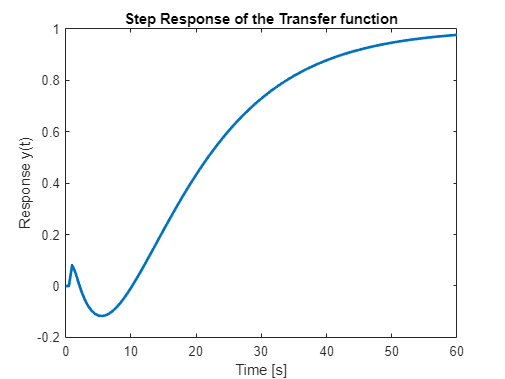


% defining variables
syms s
G = ((1-5*s)*(1-2*s)*exp(-0.5*s))/((12*s+1)*(6*s+1)*(0.3*s+1)); % the transfer function
U = 1/s; % step input
y=ilaplace(G*U); % respose of step input
dy=diff(y);
t=0:0.5:60;
t=t'; % for easier copying
y=subs(y);
doubley= double(y); % made for copying
    plot(t,y,'linewidth',2)
title("Step Response of the Transfer function")
ylabel("Response y(t)")
xlabel("Time [s]")

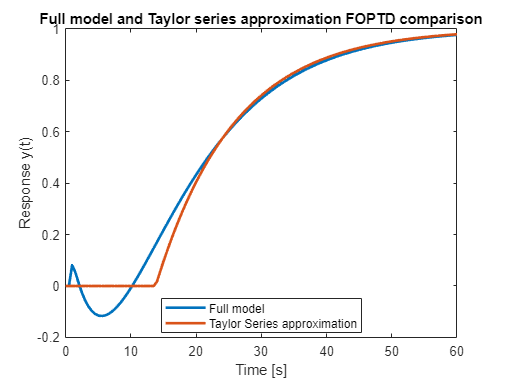


%b
G_b = exp(-13.8*s)/(12*s+1); % obtained by solving on paper
y_b=ilaplace(G_b*U);
y_b=subs(y_b);
plot(t,y,'linewidth',2)
hold on
plot(t,y_b,'linewidth',2)
hold off
ylabel("Response y(t)")
xlabel("Time [s]")
title("Full model and Taylor series approximation FOPTD comparison")
legend("Full model","Taylor Series approximation", Location="best")

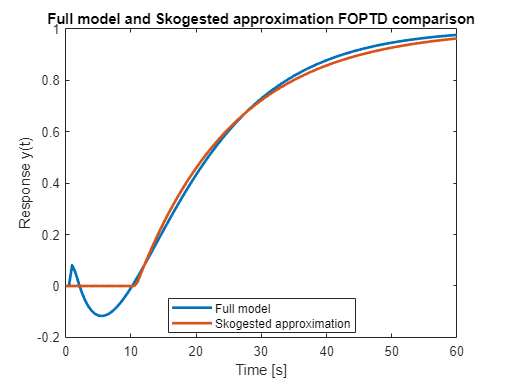


%c
G_c = exp(-10.8*s)/(15*s+1); % obtained by solving on paper
y_c=ilaplace(G_c*U);
y_c=subs(y_c);
plot(t,y,'linewidth',2)
hold on
plot(t,y_c,'linewidth',2)
hold off
ylabel("Response y(t)")
xlabel("Time [s]")
title("Full model and Skogested approximation FOPTD comparison")
legend("Full model","Skogested approximation", Location="best")


%d
t_d=14;
m = subs(dy,t_d);

$$m = \frac{595\,{\mathrm{e}}^{-\frac{9}{8}}}{2106}-\frac{220\,{\mathrm{e}}^{-\frac{9}{4}}}{513}+\frac{12190\,{\mathrm{e}}^{-45}}{20007}$$

p=double(y(find(t==t_d)))

p = 0.1705

theta = (t_d*m-p)/m

$$theta = -\frac{\frac{3080\,{\mathrm{e}}^{-\frac{9}{4}}}{513}-\frac{4165\,{\mathrm{e}}^{-\frac{9}{8}}}{1053}-\frac{170660\,{\mathrm{e}}^{-45}}{20007}+\frac{6143957457824883}{36028797018963968}}{\frac{595\,{\mathrm{e}}^{-\frac{9}{8}}}{2106}-\frac{220\,{\mathrm{e}}^{-\frac{9}{4}}}{513}+\frac{12190\,{\mathrm{e}}^{-45}}{20007}}$$

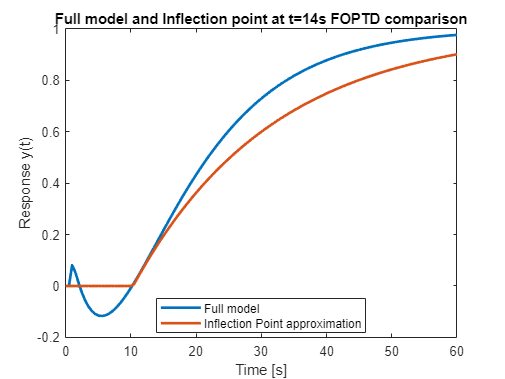

tau_d=1/m;
G_d = exp(-theta*s)/(tau_d*s+1);
y_d=ilaplace(G_d*U);
y_d=subs(y_d);
plot(t,y,'linewidth',2)
hold on
plot(t,y_d,'linewidth',2)
hold off
ylabel("Response y(t)")
xlabel("Time [s]")
title("Full model and Inflection point at t=14s FOPTD comparison")
legend("Full model","Inflection Point approximation", Location="best")

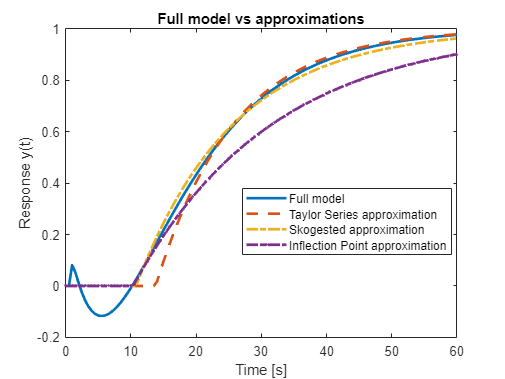


plot(t,y,'linewidth',2)
hold on
plot(t,y_b,'--','linewidth',2)
plot(t,y_c,'-.','linewidth',2)
plot(t,y_d,'-..','linewidth',2)
hold off
title("Full model vs approximations")
ylabel("Response y(t)")
xlabel("Time [s]")
legend("Full model","Taylor Series approximation","Skogested approximation","Inflection Point approximation", Location="best")

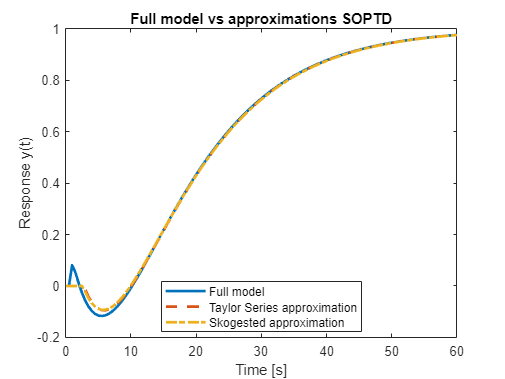



%e in excel

% f
G_2t = ((1-5*s)*exp(-2.8*s))/((12*s+1)*(6*s+1));
G_2s = ((1-5*s)*exp(-2.65*s))/((12*s+1)*(6.15*s+1));
y_2t=ilaplace(G_2t*U);
y_2t=subs(y_2t);
y_2s=ilaplace(G_2s*U);
y_2s=subs(y_2s);
y2s=double(y_2s);
plot(t,y,'linewidth',2)
hold on
plot(t,y_2t,'--','linewidth',2)
plot(t,y_2s,'-.','linewidth',2)
hold off
title("Full model vs approximations SOPTD")
ylabel("Response y(t)")
xlabel("Time [s]")
    legend("Full model","Taylor Series approximation","Skogested approximation", Location="best")